# Petri Dish: governing PDE in polar coordinates

## Theory

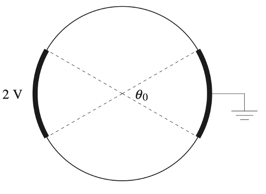

PDE: $
\nabla^2 \phi = \frac{\partial^2\phi}{\partial x^2}+ \frac{\partial^2\phi}{\partial y^2}=0
$

Polar coordinates: 


$$r=\sqrt{ x^2+y^2}$$



$$x=r\,cos(\theta)$$



$$y=r\,sin(\theta)$$


## Laplacian in polar coordinates


syms r theta x y phi(r,theta) X(r)

r_val=(x^2+y^2)^0.5

$$r\_val = \sqrt{x^{2}+y^{2}}$$

theta_val=acos(x/r_val)

$$theta\_val = \mathrm{acos}\left(\frac{x}{\sqrt{x^{2}+y^{2}}}\right)$$

The potential $\phi$ depends on r and $\theta$, so we can write (i.e. chain rule):

${{\partial \phi}\over {\partial x} }= {{\partial \phi}\over {\partial r} }\,{{\partial r}\over {\partial x} }+ {{\partial \phi}\over {\partial \theta} }\,{{\partial \theta}\over {\partial x} $      (d1)

${{\partial \phi}\over {\partial y} }= {{\partial \phi}\over {\partial r} }\,{{\partial r}\over {\partial y} }+ {{\partial \phi}\over {\partial \theta} }\,{{\partial \theta}\over {\partial y} $      (d2)

We find $\frac{\partial r}{\partial x},\,\frac{\partial \theta}{\partial x},\,\frac{\partial r}{\partial y}, \, \frac{\partial \theta}{\partial y}\$:

drx=diff(r_val,x)

$$drx = \frac{x}{\sqrt{x^{2}+y^{2}}}$$

drx=subs(drx,r_val,r)

$$drx = \frac{x}{r}$$


dry=diff(r_val,y)

$$dry = \frac{y}{\sqrt{x^{2}+y^{2}}}$$

dry=subs(dry,r_val,r)

$$dry = \frac{y}{r}$$


dthetax=diff(theta_val,x);
dthetax=simplify(dthetax,"IgnoreAnalyticConstraints",true) 

$$dthetax = -\frac{y}{x^{2}+y^{2}}$$

%Specify TRUE to relax the level of ... 
% mathematical rigor in the rewriting process.
dthetax=(subs(dthetax,r_val,r))

$$dthetax = -\frac{y}{r^{2}}$$


dthetay=diff(theta_val,y);
dthetay=simplify(dthetay,"IgnoreAnalyticConstraints",true) 

$$dthetay = \frac{x}{x^{2}+y^{2}}$$

dthetay=(subs(dthetay,r_val,r))

$$dthetay = \frac{x}{r^{2}}$$


dphix=diff(phi(r,theta),r)*drx+diff(phi(r,theta),theta)*dthetax %d1

$$dphix = \frac{x\,\frac{\partial }{\partial r}\varphi \left(r,\theta \right)}{r}-\frac{y\,\frac{\partial }{\partial \theta }\varphi \left(r,\theta \right)}{r^{2}}$$

dphiy=diff(phi(r,theta),r)*dry+diff(phi(r,theta),theta)*dthetay %d2

$$dphiy = \frac{y\,\frac{\partial }{\partial r}\varphi \left(r,\theta \right)}{r}+\frac{x\,\frac{\partial }{\partial \theta }\varphi \left(r,\theta \right)}{r^{2}}$$

Calculation of -> ${\partial^2 \phi\over \partial x^2 } = {\partial \over \partial x} \left [ {x \over r} \, {\partial \phi \over \partial r}  \right] - {\partial \over \partial x} \left [ {y \over r^2} \, {\partial \phi \over \partial \theta}  \right] $

First term (again chain rule):


$$ {\partial \over \partial x} \left [ {x \over r} \, {\partial \phi\over \partial r}  \right] =
{\partial \over \partial r} \left [ {x \over r} \, {\partial \phi \over \partial r}  \right] {\partial r \over \partial x} +
{\partial \over \partial \theta} \left [ {x \over r} \, {\partial \phi \over \partial r}  \right] {\partial \theta \over \partial x} $$


considering $x=r\,cos(\theta)$ we obtain: 


$${\partial \over \partial r} \left [ cos(\theta) \, {\partial \phi \over \partial r}  \right] {\partial r \over \partial x} + {\partial \over \partial \theta} \left [ cos(\theta)\, {\partial \phi \over \partial r}  \right] {\partial \theta \over \partial x} $$


Symbolic calculation of the above expression:

d1= diff( (cos(theta))*diff(phi,r) , r) * drx   + ... 
    diff( (cos(theta))*diff(phi,r) ,theta) *dthetax 

$$d1(r, theta) = \frac{y\,\left(\sin\left(\theta \right)\,\frac{\partial }{\partial r}\varphi \left(r,\theta \right)-\cos\left(\theta \right)\,\frac{\partial }{\partial \theta }\frac{\partial }{\partial r}\varphi \left(r,\theta \right)\right)}{r^{2}}+\frac{x\,\cos\left(\theta \right)\,\frac{\partial^{2}}{\partial r^{2}}\varphi \left(r,\theta \right)}{r}$$

Multiply by $r^3$:

d1mod=(r^3*d1);
d1mod=simplify(d1mod)

$$d1mod(r, theta) = x\,\cos\left(\theta \right)\,r^{2}\,\frac{\partial^{2}}{\partial r^{2}}\varphi \left(r,\theta \right)-y\,\cos\left(\theta \right)\,r\,\frac{\partial }{\partial \theta }\frac{\partial }{\partial r}\varphi \left(r,\theta \right)+y\,\sin\left(\theta \right)\,r\,\frac{\partial }{\partial r}\varphi \left(r,\theta \right)$$

d1mod=subs(d1mod,r*cos(theta),x);
d1mod=subs(d1mod,r*sin(theta),y)

$$d1mod(r, theta) = r\,x^{2}\,\frac{\partial^{2}}{\partial r^{2}}\varphi \left(r,\theta \right)-x\,y\,\frac{\partial }{\partial \theta }\frac{\partial }{\partial r}\varphi \left(r,\theta \right)+y^{2}\,\frac{\partial }{\partial r}\varphi \left(r,\theta \right)$$

Divide by $r^3$ to obtain d1 again:

 
d1=expand(d1mod/r^3,"IgnoreAnalyticConstraints",true)

$$d1(r, theta) = \frac{y^{2}\,\frac{\partial }{\partial r}\varphi \left(r,\theta \right)}{r^{3}}+\frac{x^{2}\,\frac{\partial^{2}}{\partial r^{2}}\varphi \left(r,\theta \right)}{r^{2}}-\frac{x\,y\,\frac{\partial }{\partial \theta }\frac{\partial }{\partial r}\varphi \left(r,\theta \right)}{r^{3}}$$

Second term (again chain rule)


$$ {\partial \over \partial x} \left [ {y \over r^2} \, {\partial \phi \over \partial \theta}  \right] =
{\partial \over \partial r} \left [ {y \over r^2} \, {\partial \phi \over \partial \theta}   \right] {\partial r \over \partial x} +
{\partial \over \partial \theta} \left [ {y \over r^2} \, {\partial \phi \over \partial \theta}  \right] {\partial \theta \over \partial x} $$


considering $y=r\,sen(\theta)$ obtaining 


$$ {\partial \over \partial x} \left [ {y \over r^2} \, {\partial \phi \over \partial \theta}  \right] =
{\partial \over \partial r} \left [ {sen(\theta) \over r} \, {\partial \phi \over \partial \theta}   \right] {\partial r \over \partial x} +
{\partial \over \partial \theta} \left [ {sin(\theta) \over r} \, {\partial \phi \over \partial \theta}  \right] {\partial \theta \over \partial x} $$


Symbolic calculation of the above expression:


d2= diff( (sin(theta)/r)*diff(phi,theta) , r) * drx + ...
    diff( (sin(theta)/r)*diff(phi,theta) ,theta) *dthetax

$$d2(r, theta) = -\frac{x\,\left(\frac{\sin\left(\theta \right)\,\frac{\partial }{\partial \theta }\varphi \left(r,\theta \right)}{r^{2}}-\frac{\sin\left(\theta \right)\,\frac{\partial }{\partial \theta }\frac{\partial }{\partial r}\varphi \left(r,\theta \right)}{r}\right)}{r}-\frac{y\,\left(\frac{\cos\left(\theta \right)\,\frac{\partial }{\partial \theta }\varphi \left(r,\theta \right)}{r}+\frac{\sin\left(\theta \right)\,\frac{\partial^{2}}{\partial \theta^{2}}\varphi \left(r,\theta \right)}{r}\right)}{r^{2}}$$

Multiply by $r^4$:


d2mod=(r^4*d2);
d2mod=expand(d2mod)

$$d2mod(r, theta) = r^{2}\,x\,\sin\left(\theta \right)\,\frac{\partial }{\partial \theta }\frac{\partial }{\partial r}\varphi \left(r,\theta \right)-r\,y\,\cos\left(\theta \right)\,\frac{\partial }{\partial \theta }\varphi \left(r,\theta \right)-r\,x\,\sin\left(\theta \right)\,\frac{\partial }{\partial \theta }\varphi \left(r,\theta \right)-r\,y\,\sin\left(\theta \right)\,\frac{\partial^{2}}{\partial \theta^{2}}\varphi \left(r,\theta \right)$$

d2mod=subs(d2mod,r*cos(theta),x);
d2mod=subs(d2mod,r*sin(theta),y)

$$d2mod(r, theta) = r\,x\,y\,\frac{\partial }{\partial \theta }\frac{\partial }{\partial r}\varphi \left(r,\theta \right)-y^{2}\,\frac{\partial^{2}}{\partial \theta^{2}}\varphi \left(r,\theta \right)-2\,x\,y\,\frac{\partial }{\partial \theta }\varphi \left(r,\theta \right)$$

Divide by $r^4$:

d2=expand(d2mod/r^4)

$$d2(r, theta) = \frac{x\,y\,\frac{\partial }{\partial \theta }\frac{\partial }{\partial r}\varphi \left(r,\theta \right)}{r^{3}}-\frac{2\,x\,y\,\frac{\partial }{\partial \theta }\varphi \left(r,\theta \right)}{r^{4}}-\frac{y^{2}\,\frac{\partial^{2}}{\partial \theta^{2}}\varphi \left(r,\theta \right)}{r^{4}}$$

We obtain $\frac{\partial^2\phi}{\partial x^2}$:

d2phix=simplify(d1-d2)

$$d2phix(r, theta) = \begin{array}{l} \frac{y^{2}\,\sigma_{1}}{r^{3}}+\frac{x^{2}\,\frac{\partial^{2}}{\partial r^{2}}\varphi \left(r,\theta \right)}{r^{2}}+\frac{y^{2}\,\frac{\partial^{2}}{\partial \theta^{2}}\varphi \left(r,\theta \right)}{r^{4}}+\frac{2\,x\,y\,\frac{\partial }{\partial \theta }\varphi \left(r,\theta \right)}{r^{4}}-\frac{2\,x\,y\,\frac{\partial }{\partial \theta }\sigma_{1}}{r^{3}}\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial }{\partial r}\varphi \left(r,\theta \right) \end{array}$$

Calculation of -> ${\partial^2 \phi\over \partial y^2 } = {\partial \over \partial y} \left [ {y \over r} \, {\partial V \over \partial r}  \right] + {\partial \over \partial y} \left [ {x \over r^2} \, {\partial V \over \partial \theta}  \right] 


$

First term (chain rule):


$$ {\partial \over \partial y} \left [ {y \over r} \, {\partial \phi \over \partial r}  \right] =
{\partial \over \partial r} \left [ {y \over r} \, {\partial \phi \over \partial r}  \right] {\partial r \over \partial y} +
{\partial \over \partial \theta} \left [ {y \over r} \, {\partial \phi \over \partial r}  \right] {\partial \theta \over \partial y} $$


considering $y=r\,sin(\theta)$ we obtain:


$$ {\partial \over \partial y} \left [ {y \over r} \, {\partial \phi \over \partial r}  \right] =
{\partial \over \partial r} \left [ {sin(\theta)} \, {\partial \phi \over \partial r}  \right] {\partial r \over \partial y} +
{\partial \over \partial \theta} \left [ {sin(\theta)} \, {\partial \phi \over \partial r}  \right] {\partial \theta \over \partial y} $$


d1= diff( (sin(theta))*diff(phi,r) , r) * dry + ...
    diff( (sin(theta))*diff(phi,r) ,theta) *dthetay

$$d1(r, theta) = \frac{x\,\left(\sin\left(\theta \right)\,\frac{\partial }{\partial \theta }\frac{\partial }{\partial r}\varphi \left(r,\theta \right)+\cos\left(\theta \right)\,\frac{\partial }{\partial r}\varphi \left(r,\theta \right)\right)}{r^{2}}+\frac{y\,\sin\left(\theta \right)\,\frac{\partial^{2}}{\partial r^{2}}\varphi \left(r,\theta \right)}{r}$$

Multiply by $r^3$:

d1mod=(r^3*d1);
d1mod=simplify(d1mod)

$$d1mod(r, theta) = y\,\sin\left(\theta \right)\,r^{2}\,\frac{\partial^{2}}{\partial r^{2}}\varphi \left(r,\theta \right)+x\,\sin\left(\theta \right)\,r\,\frac{\partial }{\partial \theta }\frac{\partial }{\partial r}\varphi \left(r,\theta \right)+x\,\cos\left(\theta \right)\,r\,\frac{\partial }{\partial r}\varphi \left(r,\theta \right)$$

d1mod=subs(d1mod,r*cos(theta),x);
d1mod=subs(d1mod,r*sin(theta),y)

$$d1mod(r, theta) = r\,y^{2}\,\frac{\partial^{2}}{\partial r^{2}}\varphi \left(r,\theta \right)+x\,y\,\frac{\partial }{\partial \theta }\frac{\partial }{\partial r}\varphi \left(r,\theta \right)+x^{2}\,\frac{\partial }{\partial r}\varphi \left(r,\theta \right)$$

Divide by $r^3$ and simplify:

d1=expand(d1mod/r^3,"IgnoreAnalyticConstraints",true)

$$d1(r, theta) = \frac{x^{2}\,\frac{\partial }{\partial r}\varphi \left(r,\theta \right)}{r^{3}}+\frac{y^{2}\,\frac{\partial^{2}}{\partial r^{2}}\varphi \left(r,\theta \right)}{r^{2}}+\frac{x\,y\,\frac{\partial }{\partial \theta }\frac{\partial }{\partial r}\varphi \left(r,\theta \right)}{r^{3}}$$

Second term (chain rule):


$$ {\partial \over \partial y} \left [ {x\over r^2} \, {\partial \phi \over \partial \theta}  \right] =
{\partial \over \partial r} \left [ {x \over r^2} \, {\partial \phi \over \partial \theta}  \right] {\partial r \over \partial y} +
{\partial \over \partial \theta} \left [ {x\over r^2} \, {\partial \phi \over \partial \theta}  \right] {\partial \theta \over \partial y} $$


considering $x=r\,cos(\theta)$ obtaining 


$$ {\partial \over \partial y} \left [ {x\over r^2} \, {\partial \phi \over \partial \theta}  \right] =
{\partial \over \partial r} \left [ {cos(\theta) \over r} \, {\partial \phi \over \partial \theta}  \right] {\partial r \over \partial y} +
{\partial \over \partial \theta} \left [ {cos(\theta) \over r} \, {\partial \phi \over \partial \theta}  \right] {\partial \theta \over \partial y} $$


Symbolic calculation of the above expression:

d2= diff( (cos(theta)/r)*diff(phi,theta) , r) * dry + ...
    diff( (cos(theta)/r)*diff(phi,theta) ,theta) *dthetay

$$d2(r, theta) = -\frac{y\,\left(\frac{\cos\left(\theta \right)\,\frac{\partial }{\partial \theta }\varphi \left(r,\theta \right)}{r^{2}}-\frac{\cos\left(\theta \right)\,\frac{\partial }{\partial \theta }\frac{\partial }{\partial r}\varphi \left(r,\theta \right)}{r}\right)}{r}-\frac{x\,\left(\frac{\sin\left(\theta \right)\,\frac{\partial }{\partial \theta }\varphi \left(r,\theta \right)}{r}-\frac{\cos\left(\theta \right)\,\frac{\partial^{2}}{\partial \theta^{2}}\varphi \left(r,\theta \right)}{r}\right)}{r^{2}}$$

Multiply by $r^4$:

d2mod=(r^4*d2);
d2mod=expand(d2mod);
d2mod=subs(d2mod,r*cos(theta),x);
d2mod=subs(d2mod,r*sin(theta),y)

$$d2mod(r, theta) = r\,y\,x\,\frac{\partial }{\partial \theta }\frac{\partial }{\partial r}\varphi \left(r,\theta \right)+x^{2}\,\frac{\partial^{2}}{\partial \theta^{2}}\varphi \left(r,\theta \right)-2\,y\,x\,\frac{\partial }{\partial \theta }\varphi \left(r,\theta \right)$$

Divide by $r^4$:

d2=expand(d2mod/r^4);

We obtain $\frac{\partial^2\phi}{\partial y^2}$:

d2phiy=simplify(d1+d2)

$$d2phiy(r, theta) = \begin{array}{l} \frac{x^{2}\,\sigma_{1}}{r^{3}}+\frac{y^{2}\,\frac{\partial^{2}}{\partial r^{2}}\varphi \left(r,\theta \right)}{r^{2}}+\frac{x^{2}\,\frac{\partial^{2}}{\partial \theta^{2}}\varphi \left(r,\theta \right)}{r^{4}}-\frac{2\,x\,y\,\frac{\partial }{\partial \theta }\varphi \left(r,\theta \right)}{r^{4}}+\frac{2\,x\,y\,\frac{\partial }{\partial \theta }\sigma_{1}}{r^{3}}\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial }{\partial r}\varphi \left(r,\theta \right) \end{array}$$


lapl=simplify(d2phix+d2phiy,"IgnoreAnalyticConstraints",true)

$$lapl(r, theta) = \frac{\left(x^{2}+y^{2}\right)\,\left(r^{2}\,\frac{\partial^{2}}{\partial r^{2}}\varphi \left(r,\theta \right)+r\,\frac{\partial }{\partial r}\varphi \left(r,\theta \right)+\frac{\partial^{2}}{\partial \theta^{2}}\varphi \left(r,\theta \right)\right)}{r^{4}}$$

lapl=subs(lapl,x^2+y^2,r^2)

$$lapl(r, theta) = \frac{r^{2}\,\frac{\partial^{2}}{\partial r^{2}}\varphi \left(r,\theta \right)+r\,\frac{\partial }{\partial r}\varphi \left(r,\theta \right)+\frac{\partial^{2}}{\partial \theta^{2}}\varphi \left(r,\theta \right)}{r^{2}}$$

## Results

lapl=expand(lapl)

$$lapl(r, theta) = \frac{\frac{\partial }{\partial r}\varphi \left(r,\theta \right)}{r}+\frac{\frac{\partial^{2}}{\partial \theta^{2}}\varphi \left(r,\theta \right)}{r^{2}}+\frac{\partial^{2}}{\partial r^{2}}\varphi \left(r,\theta \right)$$

PDE in polar coordinates:


$$\frac{1}{r}{\frac{\partial \phi \left(r,\theta \right)}{\partial r}}+\frac{1}{r^2}{\frac{\partial^2 \phi \left(r,\theta \right)}{\partial \theta^2 }}{+\frac{\partial^2 \phi \left(r,\theta \right)}{\partial r^2 }=0$$
